# Hippocampus 

## parameter

subject ='Group';
plot_window=[1 25 1920 1080];
home_dir = '/bigvault/Projects/seeg_pointing';
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';

index = [7,13,25,31,43,49];
bd_id = [index,index+18*6]; 
non_bd_id = [index+18*3,index+18*9]; 

## Data input

% not remove epilespsy
data = load_mat([group_dir,'wavelet/wavelet_raw.mat']);
data_bd = data.bd;
data_non_bd = data.non_bd;

% remove epilespsy where kurt>5
data = load_mat([group_dir,'wavelet/wavelet_kurt.mat']);
data_bd = data.bd;
data_non_bd = data.non_bd;

% remove epilespsy where kurt>5 and manual select
wavelet_manual = load_mat([group_dir,'wavelet/wavelet_manual.mat']);
data_bd = wavelet_manual.bd;
data_non_bd = wavelet_manual.non_bd;

% delete channel 52,53
data_bd = data_bd(:,[1:51,54:57],:,:);
data_non_bd = data_non_bd(:,[1:51,54:57],:,:);

## Data extract

% condition
temp = squeeze(mean(data_bd(:,:,:,:),1));
bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd(:,:,:,:),1)); 
non_bd = permute(temp,[2,3,1]);

% position
temp = squeeze(mean(data_bd([7,13],:,:,:),1));
wavelet_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_bd([6,12],:,:,:),1)); 
wavelet_pre_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([7,13],:,:,:),1)); 
wavelet_non_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([6,12],:,:,:),1)); 
wavelet_pre_non_bd = permute(temp,[2,3,1]);

% not remove 
plt_rsa_sd(bd,non_bd,'wavelet');
sgtitle('not remove epilepsy(conidtion)')

plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet');
sgtitle('not remove epilepsy(position)')

% kurt remove 
plt_rsa_sd(bd,non_bd,'wavelet');
sgtitle('kurt remove epilepsy(conidtion)')

plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet');
sgtitle('kurt remove epilepsy(position)')

% manual remove 
plt_rsa_sd(bd,non_bd,'wavelet');
sgtitle('manual remove epilepsy(conidtion)')

plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet');
sgtitle('manual remove epilepsy(position)')

## Condition

% The difference cluster in two condition
freq = 1:20;
time = [512*2.5+1:512*7.5];
[cp, pp, ~, ~]= plt_rsa_sd_perm(bd(freq,time,:),non_bd(freq,time,:),'wavelet');
sgtitle('manual remove epilepsy(conidtion)')

mask = nan(size(bd(freq,time,:),[1,2]));
mask(cp{1,3})=1;
figure
plt_imagesc(mask,'wavelet_s');
title(['p=',num2str(pp(3))])

% The difference cluster in two condition
freq = 1:12;
time = [512*2.5+1:512*5];
[cp, pp, ~, ~]= plt_rsa_sd_perm(bd(freq,time,:),non_bd(freq,time,:),'wavelet');
sgtitle('manual remove epilepsy(conidtion)')

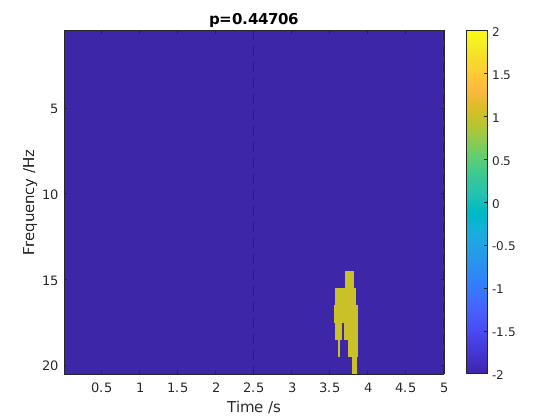

% condition campare with zero
t1=[];p1=[];
t2=[];p2=[];
for i=1:size(wavelet_bd,1)
    for j= 1:size(wavelet_bd,2)
        [~,p1(i,j),~,STATS] = ttest(squeeze(bd(i,j,:)));
        t1(i,j) = STATS.tstat;
        [~,p2(i,j),~,STATS] = ttest(squeeze(non_bd(i,j,:)));
        t2(i,j) = STATS.tstat;
    end

end
figure 
subplot(2,1,1)
plt_imagesc((p1<=0.05).*t1,'wavelet')
title('bd t-value')

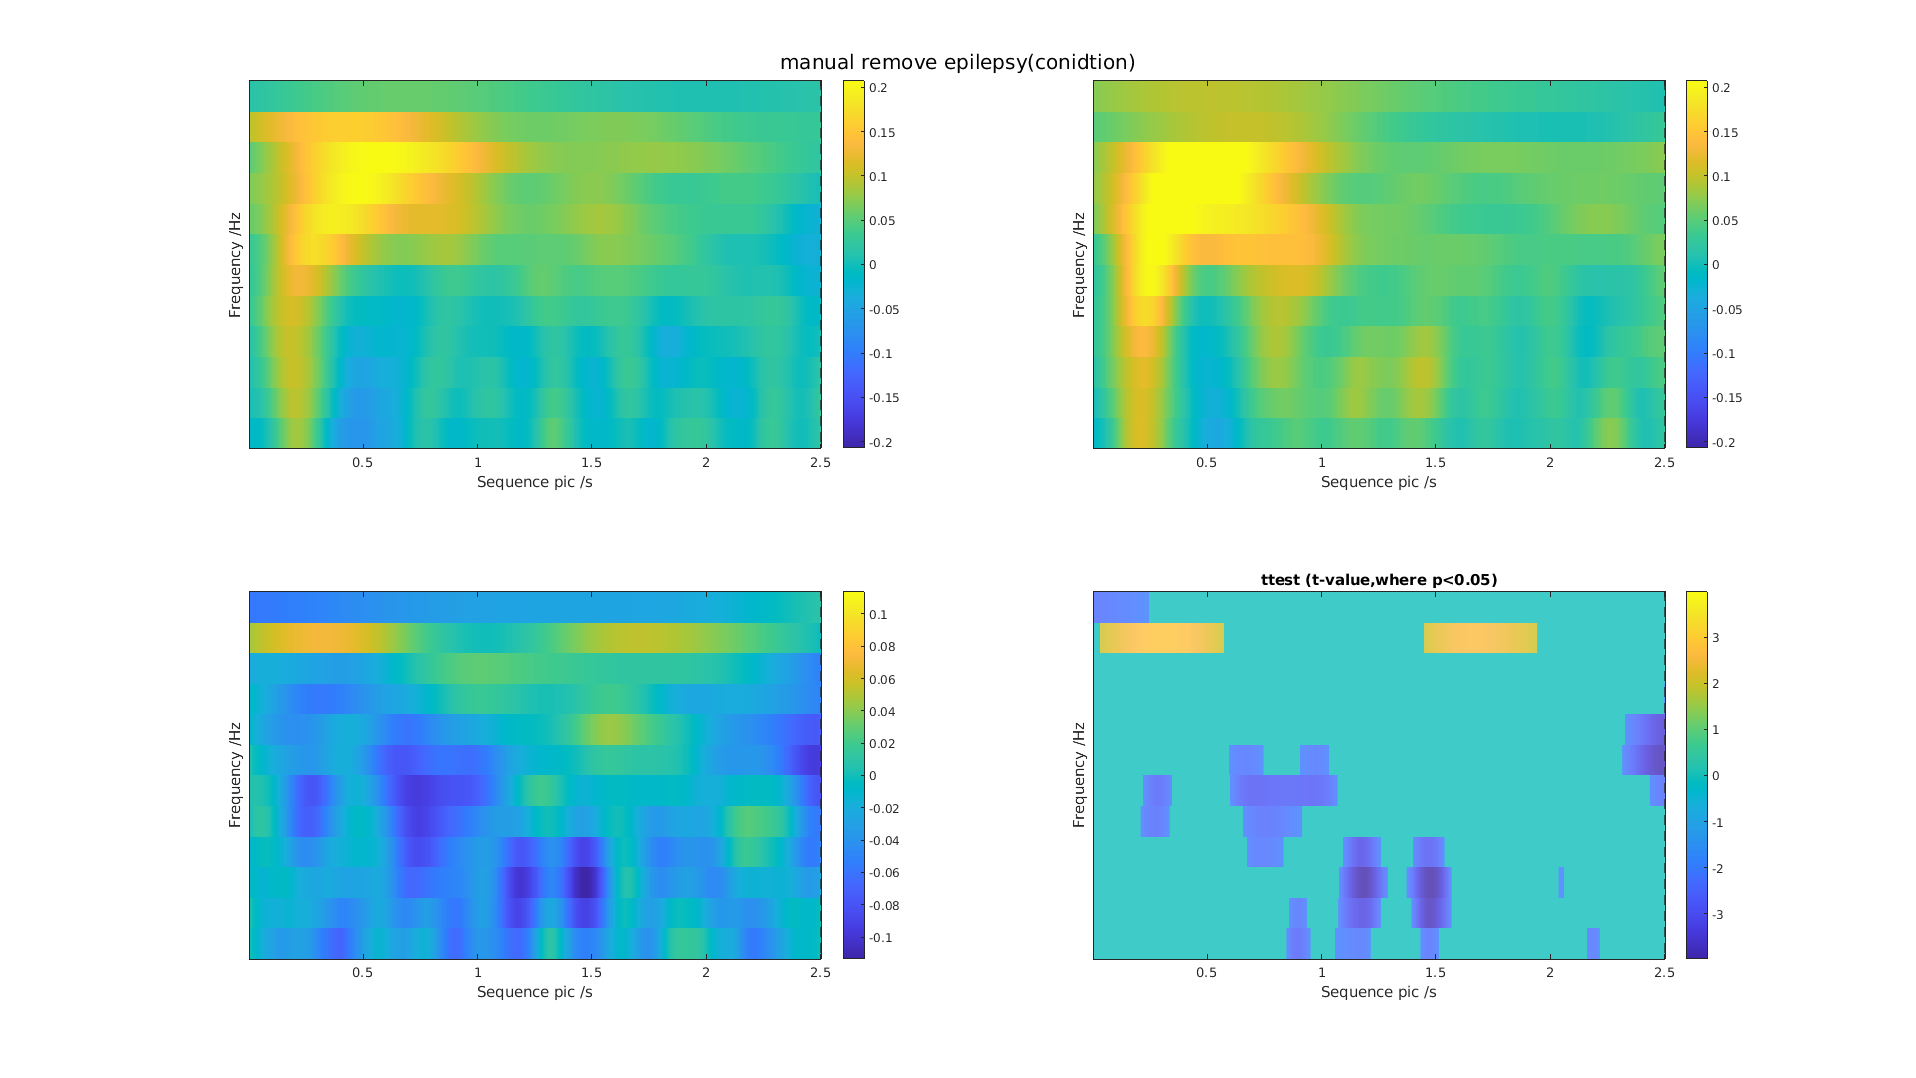

subplot(2,1,2)

plt_imagesc((p2<=0.05).*t2,'wavelet')
title('non bd t-value')
sgtitle('campare with zeros')

## Position

% Theta power position change
freq = 1:20;
time = [512*2.5+1:512*7.5];
plt_rsa_sd(wavelet_bd(freq,time,:),wavelet_non_bd(freq,time,:),'wavelet_s');
sgtitle('manual remove epilepsy(position)')
for i=1:4
    subplot(2,2,i)
    yline(7,'-');xline(610,'-')
end

% The difference cluster in two condition
freq = 1:20;
time = [512*2.5+1:512*7.5];

ans = 7.5474

[cp, pp, ~, ~]= plt_rsa_sd_perm(wavelet_bd(freq,time,:),wavelet_non_bd(freq,time,:),'wavelet_s');
sgtitle('manual remove epilepsy(position)')

% The difference cluster in two condition

ans = 6.8691

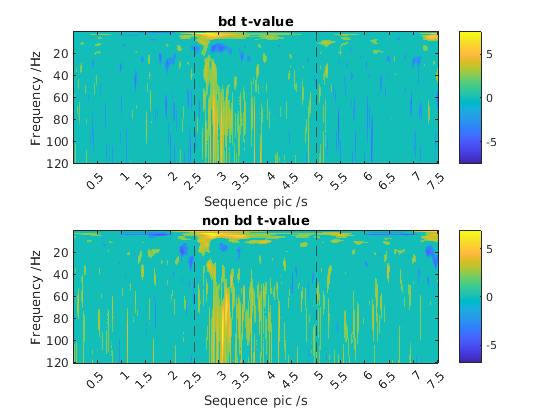

freq = 1:5;

time = [512*2.5+1:512*5];
[cp, pp, ~, ~]= plt_rsa_sd_perm(wavelet_bd(freq,time,:),wavelet_non_bd(freq,time,:),'wavelet_s');
sgtitle('manual remove epilepsy(position)')

% The difference cluster in two condition
freq = 21:120;
time = [512*2.5+1:512*7.5];
[cp, pp, ~, ~]= plt_rsa_sd_perm(wavelet_bd(freq,time,:),wavelet_non_bd(freq,time,:),'wavelet_s');

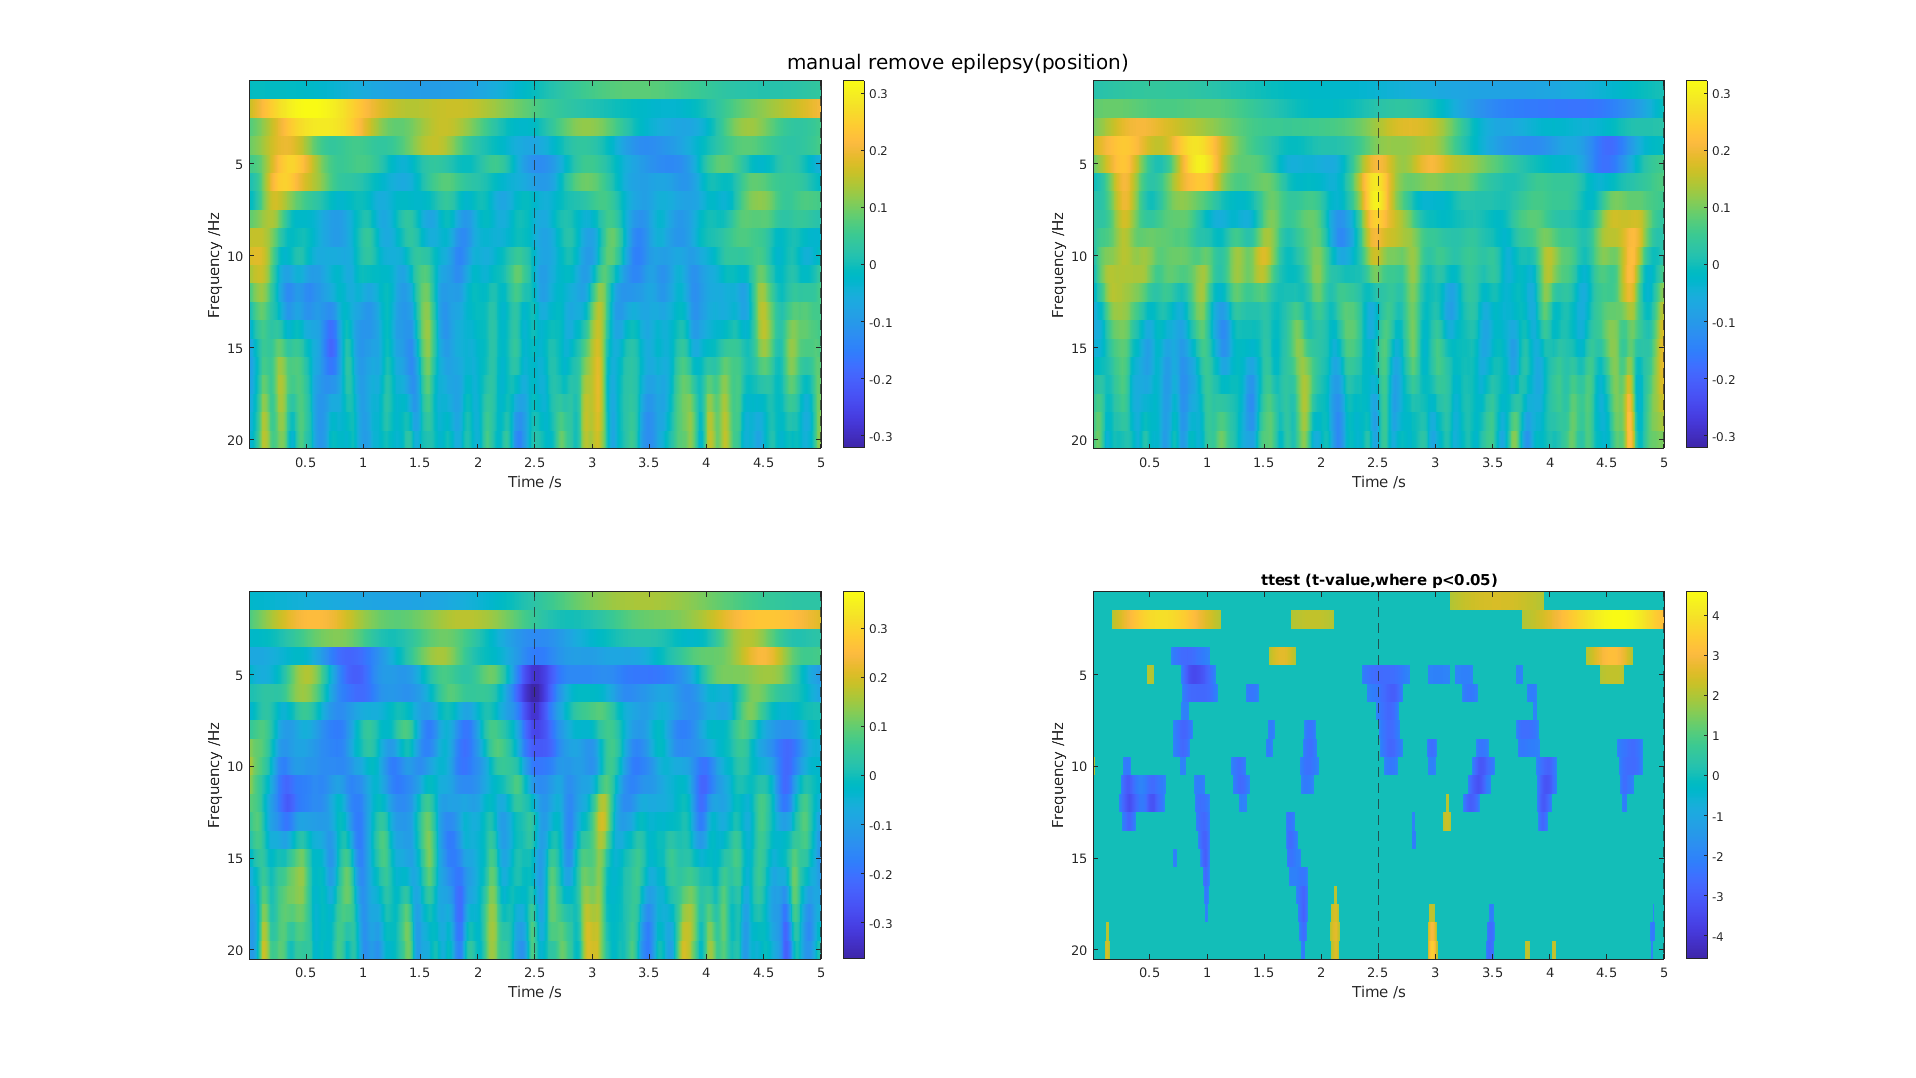

for i=1:4

    subplot(2,2,i)
    yticks(0:10:100);
    yticklabels(20:10:120);
end

sgtitle('manual remove epilepsy(position)')


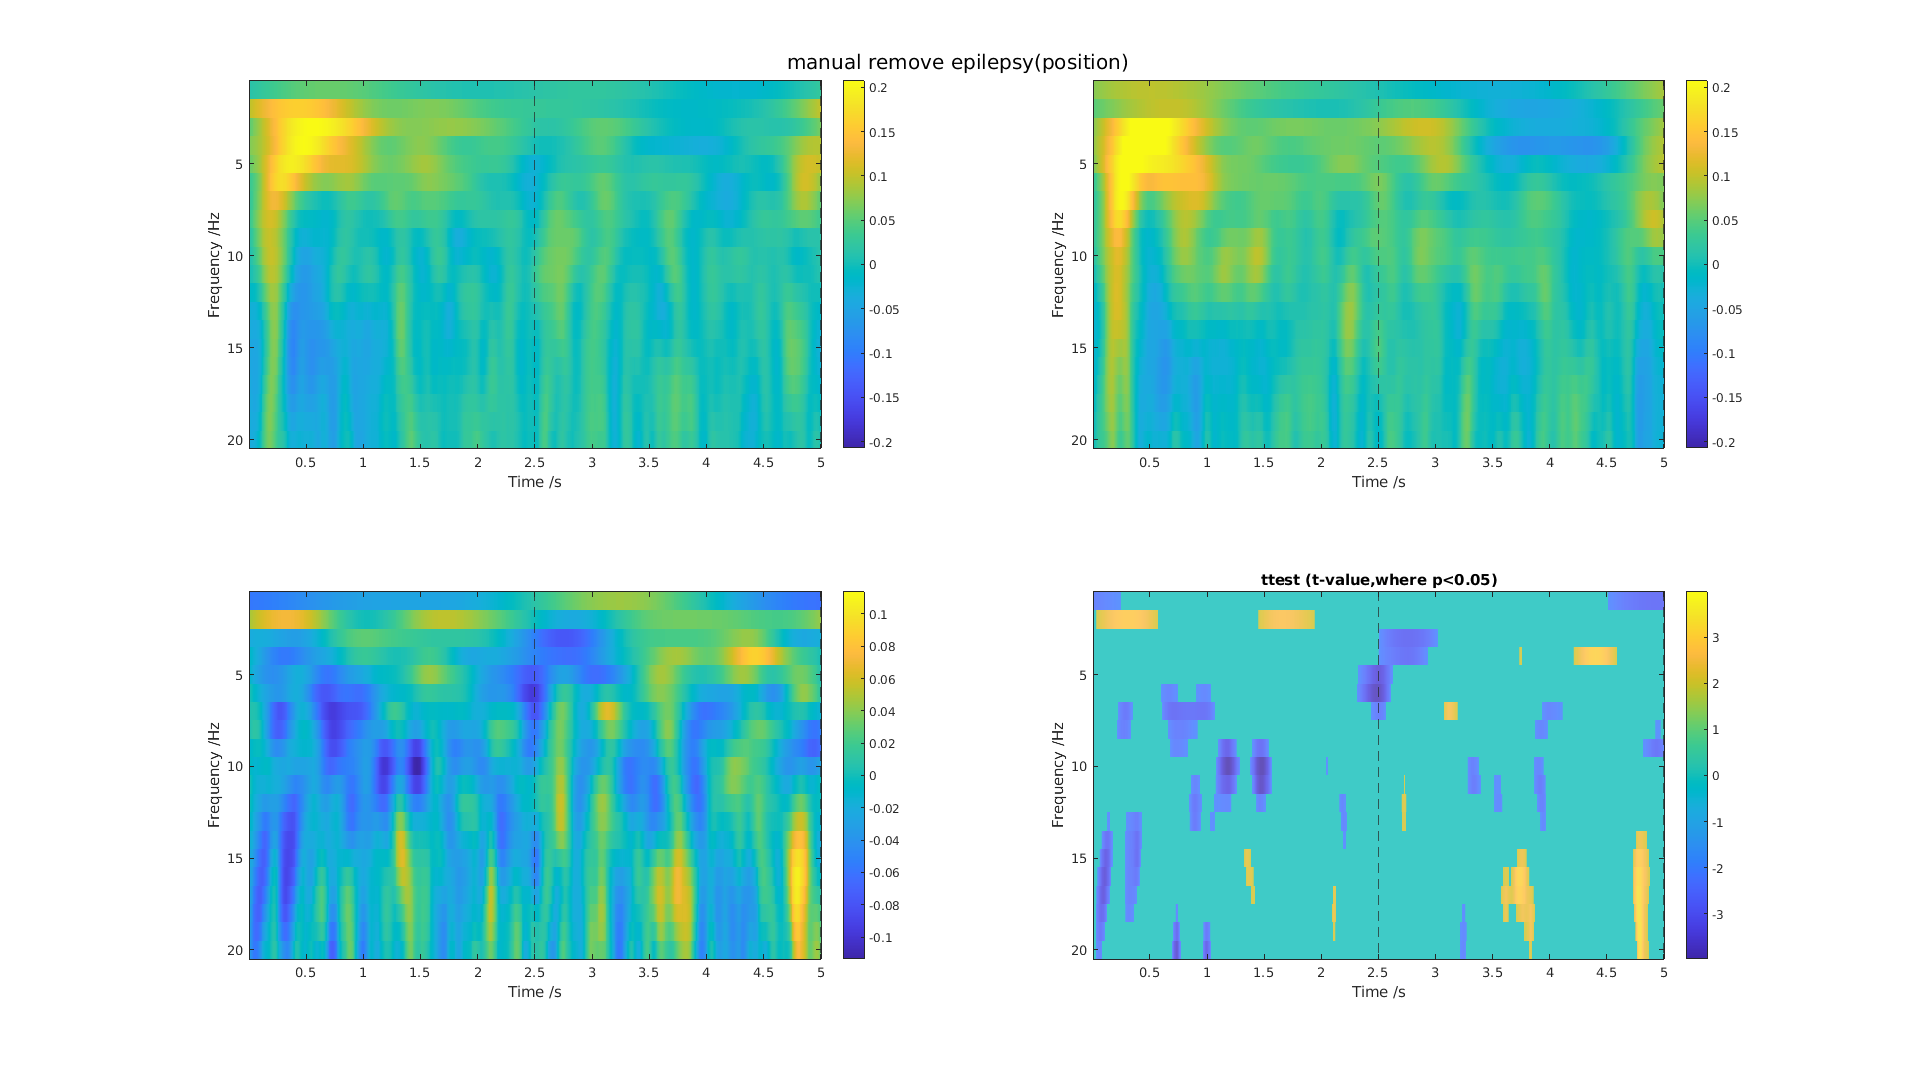

mask = nan(size(wavelet_bd(freq,time,:),[1,2]));
mask(cp{1,2})=1;

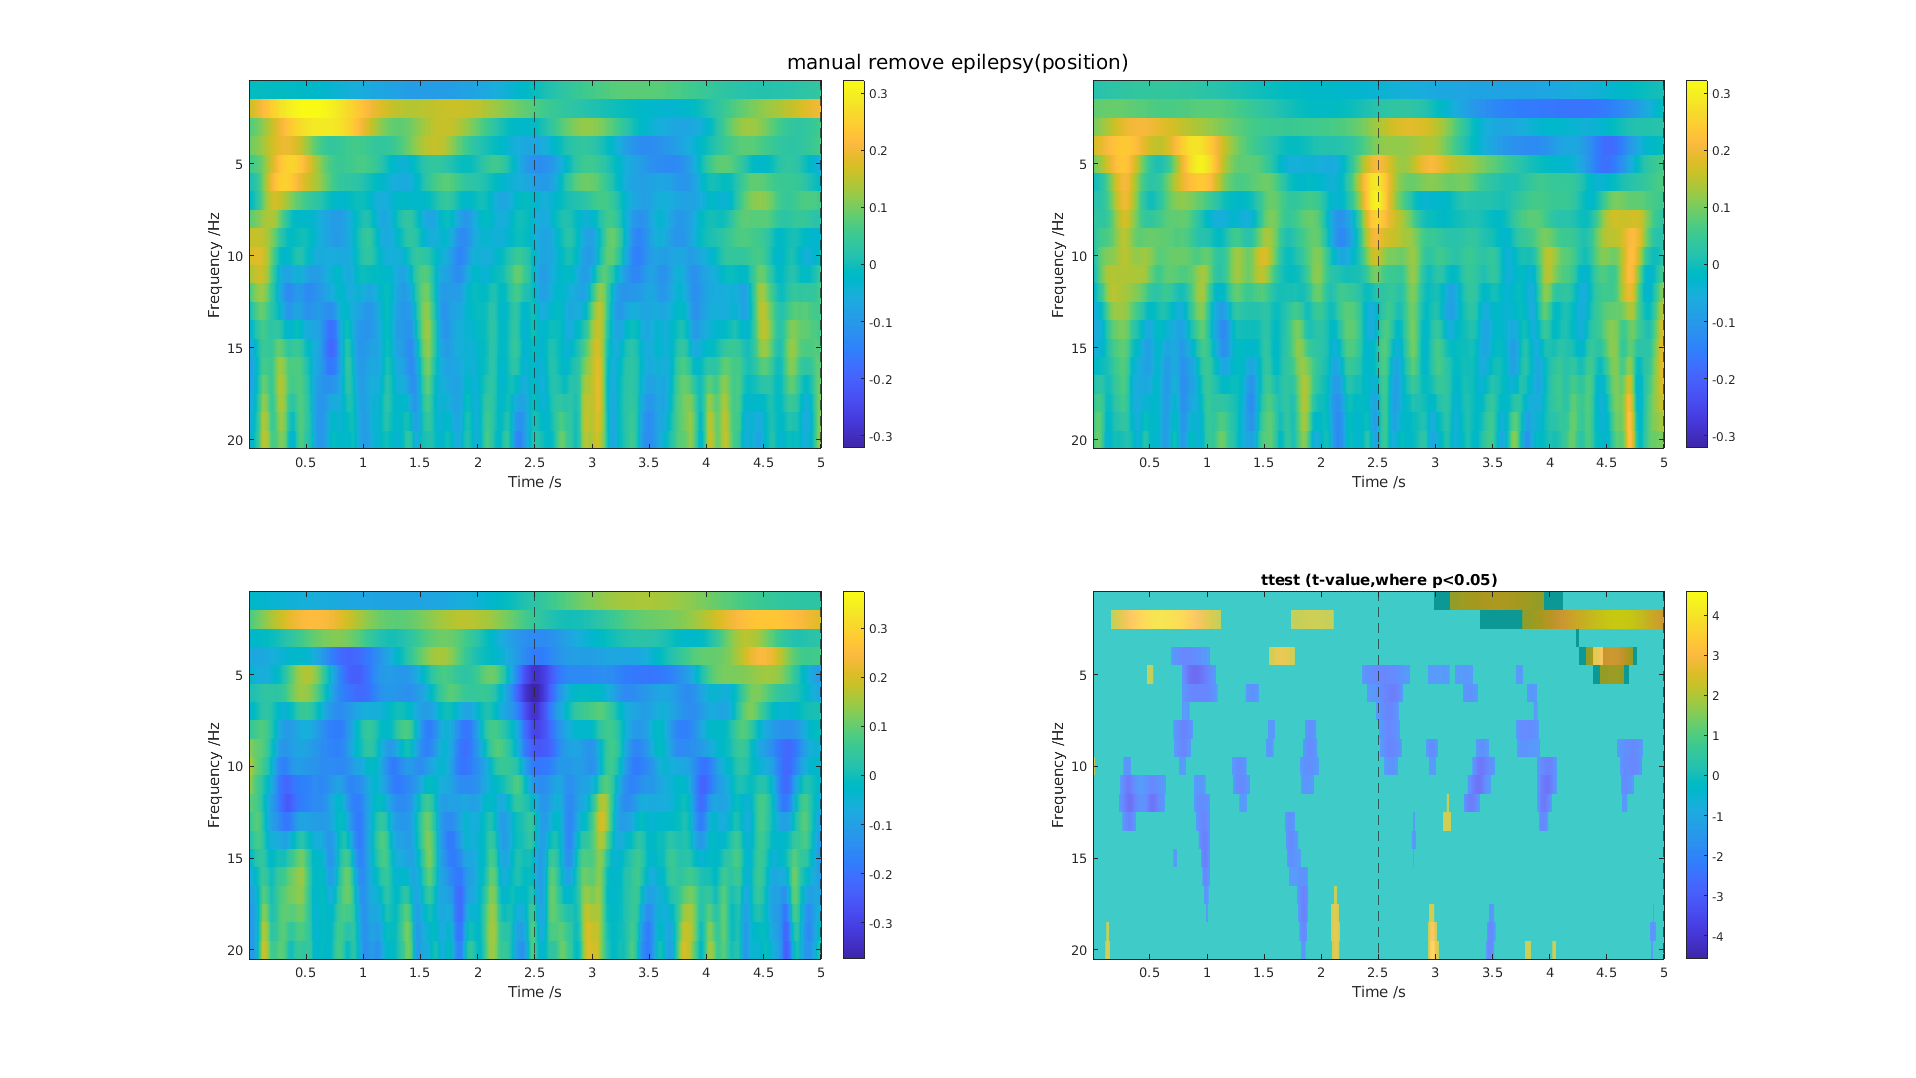

figure

plt_imagesc(mask,'wavelet_s');
title(['p=',num2str(pp(2))])

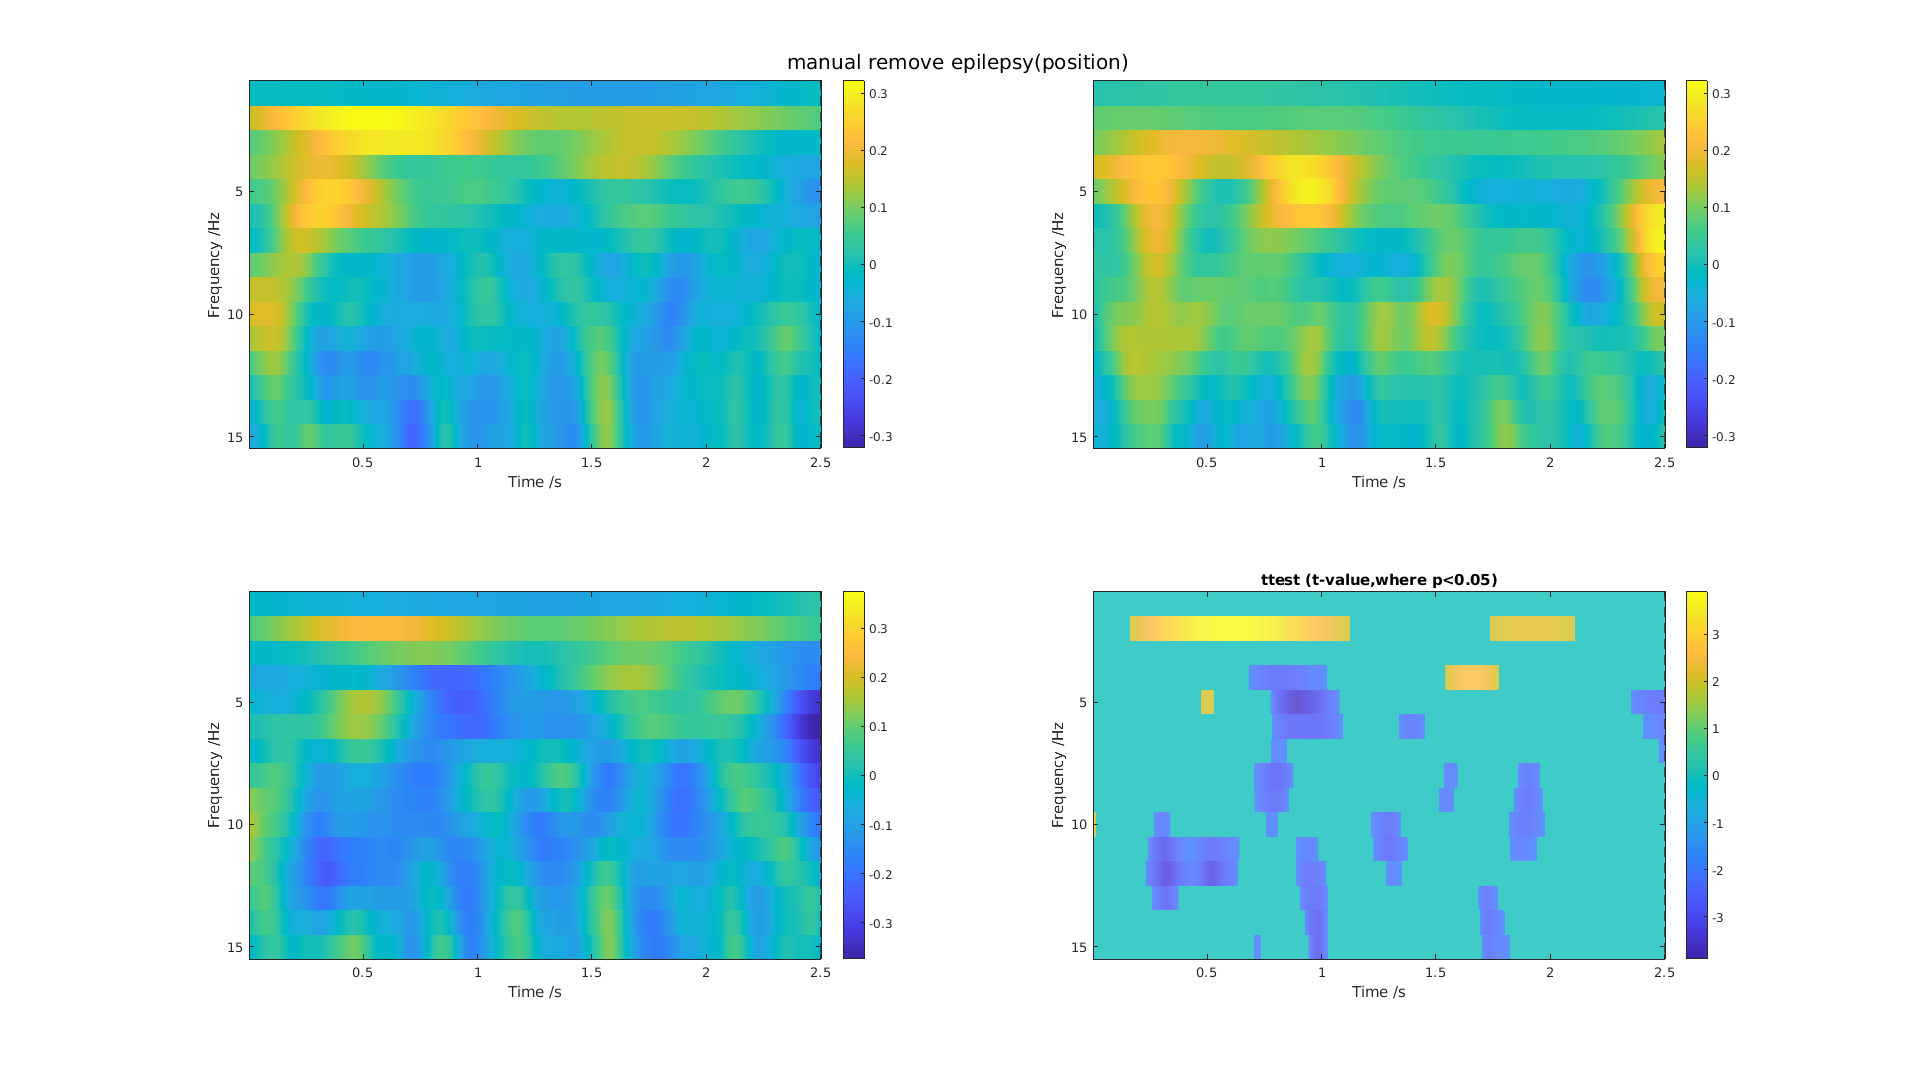

% condition campare with zero
t1=[];p1=[];
t2=[];p2=[];

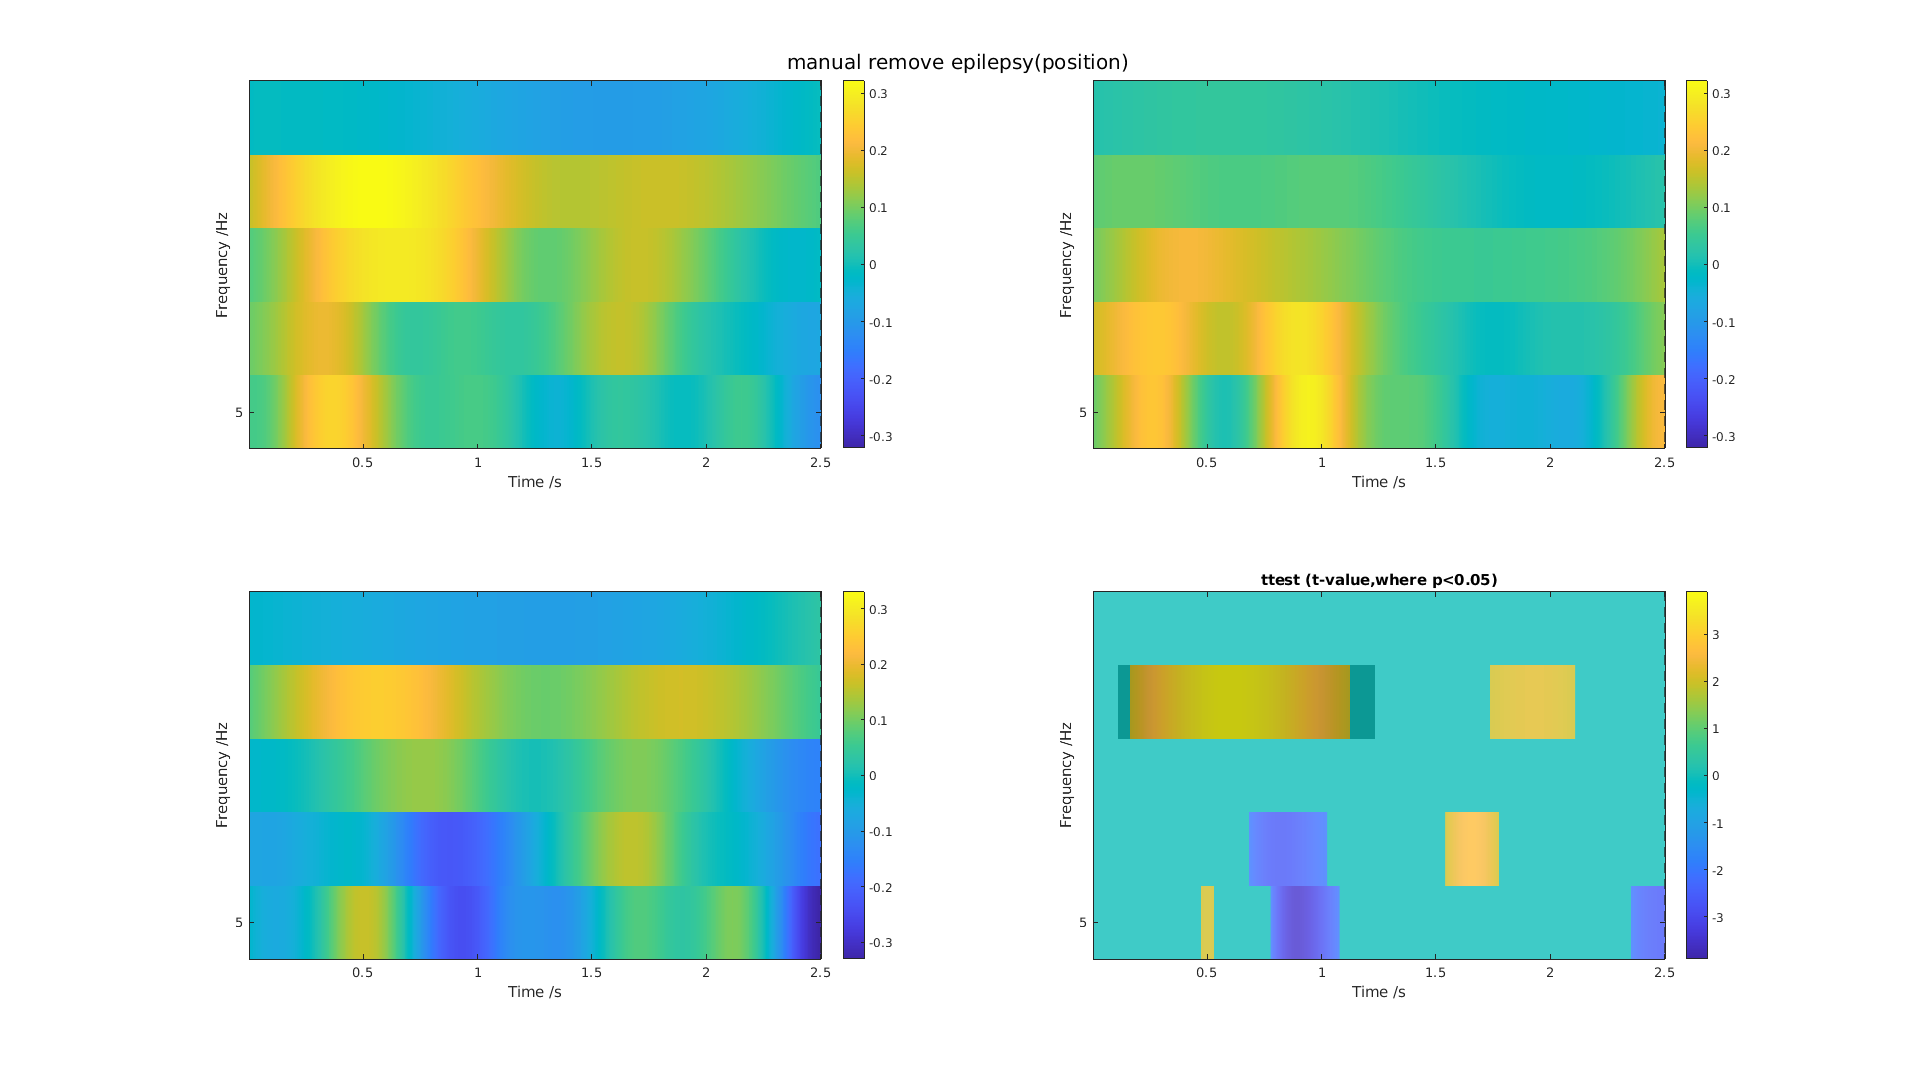

for i=1:size(wavelet_bd,1)

    for j= 1:size(wavelet_bd,2)
        [~,p1(i,j),~,STATS] = ttest(squeeze(wavelet_bd(i,j,:)));
        t1(i,j) = STATS.tstat;
        [~,p2(i,j),~,STATS] = ttest(squeeze(wavelet_bd(i,j,:)));
        t2(i,j) = STATS.tstat;

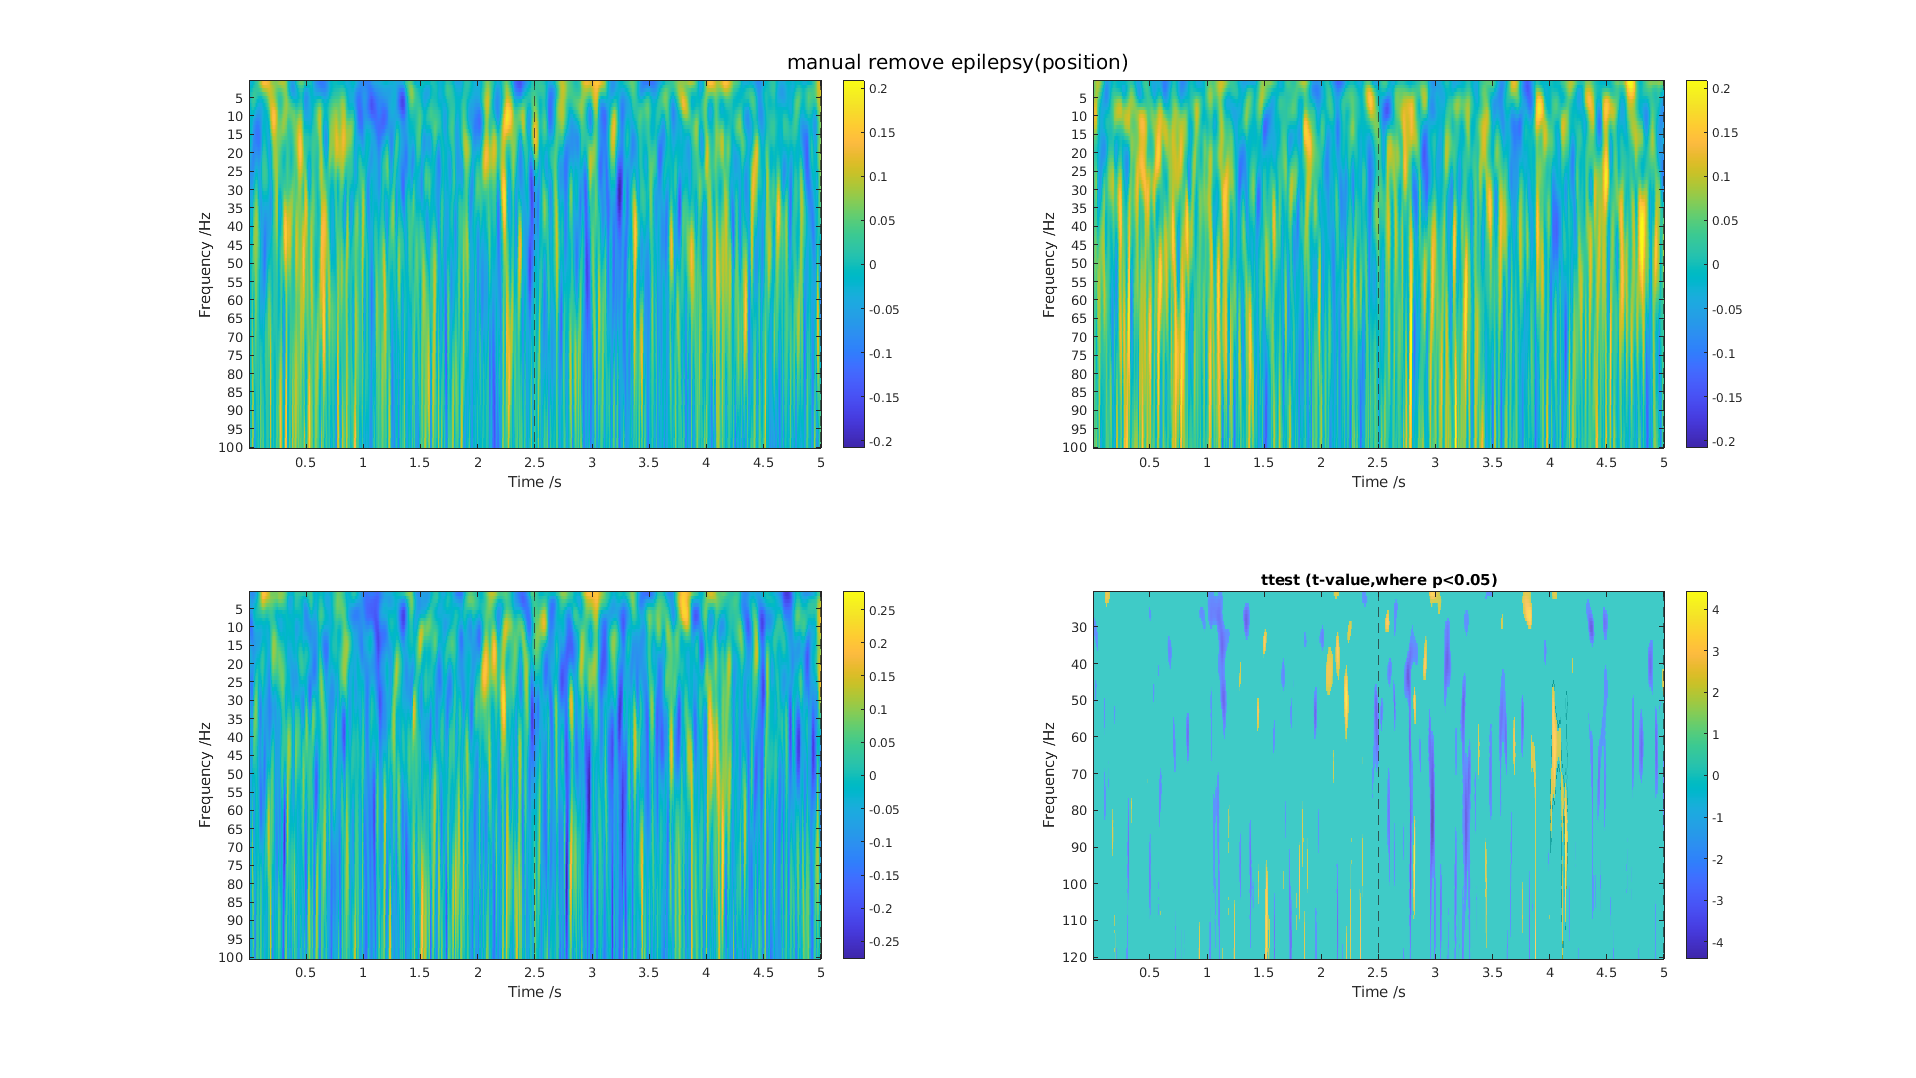

    end
end
figure 
subplot(2,1,1)
plt_imagesc((p1<=0.05).*t1,'wavelet')
title('bd t-value')
subplot(2,1,2)

plt_imagesc((p2<=0.05).*t2,'wavelet')
title('non bd t-value')
sgtitle('campare with zeros')

### Boundary turns vs nonBoundary turns

#### total

[cp, pp, ~, ~]= plt_rsa_sd_perm(bd,non_bd,'wavelet') 

plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet') 

## remove epilespsy

% manual 
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';
% load wavlet data for subject
data_bd = load_mat([group_dir,'wavelet/wavele_manual_1.mat']);
data_non_bd = load_mat([group_dir,'wavelet/wavele_manual_2.mat']);

data_bd = data_normalized_bd;
data_non_bd = data_normalized_non_bd;


% condition
temp = squeeze(mean(data_bd(:,:,:,:),1));
bd = permute(temp,[2,3,1]);


ans = 6.8045

temp  = squeeze(mean(data_non_bd(:,:,:,:),1)); 
non_bd = permute(temp,[2,3,1]);


ans = 6.8045

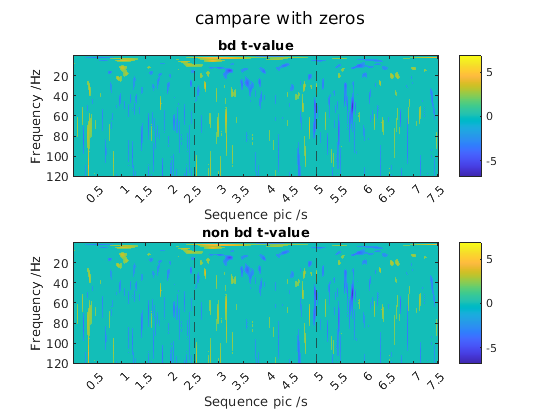

% position
temp = squeeze(mean(data_bd([7,13],:,:,:),1));

wavelet_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_bd([6,12],:,:,:),1)); 
wavelet_pre_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([7,13],:,:,:),1)); 
wavelet_non_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([6,12],:,:,:),1)); 
wavelet_pre_non_bd = permute(temp,[2,3,1]);

[cp, pp, ~, ~]= plt_rsa_sd_perm(bd,non_bd,'wavelet')
sgtitle('manual remove epilepsy(conidtion)')

[cp, pp, ~, ~]= plt_rsa_sd_perm(wavelet_bd,wavelet_non_bd,'wavelet')
sgtitle('manual remove epilepsy(position)')

#### 2 turns

% zoom in 1-25Hz
subject='subject1-27 (2turn)'
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    for seqi=1:6
    data_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),seqi+6:6:18)),3);
    data_non_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),seqi+6:6:18)),3);
    end
end
plt_wavelet_sd(data_bd, data_non_bd, subject, plot_window)    

## Theta (permutation)

freq = 1:20;
data1 = wavelet_bd(freq,:,:);
data2 = wavelet_non_bd(freq,:,:);
[cp, pp, ~, ~]= plt_rsa_sd_perm(data1,data2,'wavelet');

% linear mixed model
sub = data_epoch.info.sub_id;
sub_ids = [sub;sub];
chan_id = [1:57,1:57]';
condition = [ones(57,1);zeros(57,1)];
result_lme=zeros([size(data1,[1,2]),3]);
for i= 1:size(data1,1)
    disp(i)
    result_temp=zeros([size(data1,2),3]);
    parfor j= 1:size(data1,2)
        data = [squeeze(data1(i,j,:));squeeze(data2(i,j,:))];
        tbl = table(data,sub_ids,chan_id,condition,'VariableNames',{'wavelet','subject','channel','condition'});
        lme = fitlme(tbl,'wavelet~condition+(condition|subject)+(condition|channel)');
        temp = dataset2table(lme.Coefficients);
        result_temp(j,:)=[temp.Estimate(2),temp.tStat(2),temp.pValue(2)];
        if j/500==0
            disp(j)
        end
    end
    result_lme(i,:,:) =result_temp; 
end

figure;plt_imagesc((result_lme(:,:,3)<0.05).*result_lme(:,:,2),'wavelet_s')
title('lme')

% mask
i=1;
mask = NaN(size(data1(freq,:,1)));
mask(cp{1, i}) = 1;
figure;plt_imagesc(mask,'wavelet')
title(['wavelet Boundary and non Boundary Cluster-based Permutation  (largest cluster, p =',num2str(pp(i)),')'])
set(gcf, 'Position', [1 25 1920 1080]);

% data in the mask
res_bd =[];
res_non_bd =[];
for chani = 1:size(data1,3)

    res_bd = nanmean(squeeze(data1(:,:,chani)).*mask,[1,2]);
    res_non_bd = nanmean(squeeze(data2(:,:,chani)).*mask,[1,2]);

    result(chani,:) = [res_bd;res_non_bd];
end
figure
plt_box_line(result,{'bd','on bd'})
title(['cluster',num2str(i)])
sum(result(:,1)>result(:,2))

% linear mixed-effects model for each pixel(control group effect)
sub = data_epoch.info.sub_id;
sub_ids = [sub;sub];
chan_id = [1:57,1:57]';
condition = [ones(57,1);zeros(57,1)];
result_lme=zeros([size(data1,[1,2]),3]);
for i= 1:size(data1,1)
    disp(i)
    result_temp=zeros([size(data1,2),3]);
    parfor j= 1:size(data1,2)
        data = [squeeze(data1(i,j,:));squeeze(data2(i,j,:))];
        tbl = table(data,sub_ids,chan_id,condition,'VariableNames',{'wavelet','subject','channel','condition'});
        lme = fitlme(tbl,'wavelet~condition+(condition|subject)+(condition|channel)');
        temp = dataset2table(lme.Coefficients);
        result_temp(j,:)=[temp.Estimate(2),temp.tStat(2),temp.pValue(2)];
        if j/500==0
            disp(j)
        end
    end
    result_lme(i,:,:) =result_temp;
end
figure;plt_imagesc((result_lme(:,:,3)<0.05).*result_lme(:,:,2),'wavelet_s')
title('lme')
figure;plt_imagesc(result_lme(:,:,1),'wavelet_s')

## Theta (anova)

wavelet = cat(3, wavelet_bd,wavelet_pre_bd,wavelet_non_bd,wavelet_pre_non_bd);
condition  = reshape(repmat([1,1,2,2], 10, 1),[],1);
position  = reshape(repmat([1,2,1,2], 10, 1),[],1);
p2=[];
for i = 1:size(wavelet,1)
    for j=1:size(wavelet,2)
        p2(i,j,:) = anovan(squeeze(wavelet(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

% ttest
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    wavelet_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),[7,13])),3);
    wavelet_non_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),[7,13])),3);
end

figure
subplot(1,2,1)
imagesc(mean(wavelet_bd,3))
caxis([-0.4,0.4])
yticks(0:20:120);
        yticklabels([0:20:120]);
        ylabel('Frequency /Hz');
        xticks(0:256:7.5*512);
        xticklabels([0:256:7.5*512]/512);
        xlabel('Sequence pic /s')
        xline(2.5*512,'--')
        xline(5*512,'--')
        colorbar()
colorbar()
subplot(1,2,2)
imagesc(mean(wavelet_non_bd,3))
caxis([-0.4,0.4])
yticks(0:20:120);
        yticklabels([0:20:120]);
        ylabel('Frequency /Hz');
        xticks(0:256:7.5*512);
        xticklabels([0:256:7.5*512]/512);
        xlabel('Sequence pic /s')
        xline(2.5*512,'--')
        xline(5*512,'--')
        colorbar()
colorbar()
plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet')

% mask combain  and anova
p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
CC = bwconncomp(anova_condition);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(1)}) = 1;
figure;imagesc(mask)
title('mask(anovan)')
mask_anova2 = mask;

p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:3
    subplot(2,2,i)
    if i<4
        imagesc(a(:,:,i))
        title(['anovan: ',anovan_name{i}])
    else
        imagesc(pic_corr_h)
        title('Mask')
    end
    yticks(0:20:120);
    yticklabels([0:20:120]);
    ylabel('Object pic /s')
    xticks(0:256:7.5*512);
    xticklabels([0:256:7.5*512]/512);
    xlabel('Sequence pic /s')
    xline(2.5*512,'--')
    xline(5*512,'--')
    colorbar()
end
set(gcf, 'Position', [1 25 1920 1080]);

% plot anova result condition(anova 2*2, mask ttest)
mask_anova=mask_anova2;
data = [];
data(1,1,:) = squeeze(mean(mean(wavelet_bd.*mask_anova,1),2));
data(1,2,:) = squeeze(mean(mean(wavelet_pre_bd.*mask_anova,1),2));
data(2,1,:) = squeeze(mean(mean(wavelet_non_bd.*mask_anova,1),2));
data(2,2,:) = squeeze(mean(mean(wavelet_pre_non_bd.*mask_anova,1),2));

figure
clim = [-0.5,0.5];
subplot(2,3,1)
temp = wavelet_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,2)
temp = wavelet_non_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,3)
temp = wavelet_pre_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('pre Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,4)
temp = wavelet_pre_non_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('pre non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,5)
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')
subplot(2,3,6)
imagesc(mask_anova)
title('Mask')
yticks(0:20:120);
yticklabels([0:20:120]);
ylabel('Object pic /s')
xticks(0:256:7.5*512);
xticklabels([0:256:7.5*512]/512);
xlabel('Sequence pic /s')
xline(2.5*512,'--')
xline(5*512,'--')
colorbar()
sgtitle('obj2seq mask')

% permutest all 18 picture


% permutation only 1000 times
tic
[clusters_perm, p_perm, t_sums_perm, permutation_distribution ] = permutest(wavelet_bd,wavelet_non_bd,true,0.05,1000);
toc


% permutest p=0.05
i=1;
mask = NaN(size(data_bd(:,:,1)));
mask(clusters_perm{1, i}) = 1;
figure;plt_imagesc(mask,'wavelet')
title(['wavelet Boundary and non Boundary Cluster-based Permutation  (largest cluster, p =',num2str(p_perm(i)),')'])
set(gcf, 'Position', [1 25 1920 1080]);

% anova   position(2,[boundary, non_boundary])*position(6,[1:6])
wavelet=[];
for pici =1:6
wavelet = cat(3, wavelet,cell2matrix(wavelet_subject.data_bd(:,[pici,pici+6,pici+12])));
end
for pici =1:6
wavelet = cat(3, wavelet,cell2matrix(wavelet_subject.data_non_bd(:,[pici,pici+6,pici+12])));
end
condition  = reshape(repmat([1,2], 10*6, 1),[],1);
position  = reshape(repmat([1:6,1:6], 10, 1),[],1);
p6=[];
for i = 1:size(wavelet,1)
    for j=1:size(wavelet,2)
        p6(i,j,:) = anovan(squeeze(wavelet(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

% compare anova mask in 2*2 and 2*6
p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
BW_anova = bwperim(mask_anova2);
CC = bwconncomp(anova_condition);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(6)}) = 1;
figure;imagesc(max(mask,BW_anova*2))
title('mask(anovan)')
mask_anova6 = mask;

p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
          plt_imagesc(max(a(:,:,i),BW_anova*2),'wavelet');
          title(['anovan: ',anovan_name{i}])
    else
        plt_imagesc(max(mask_anova6,BW_anova*2),'wavelet');
        title('mask(anovan)')
    end
end
set(gcf, 'Position', [1 25 1920 1080]);

% plot anova result condition(anova 2*6, mask ttest)
data = [];
for pici=1:6
    data(1,pici,:) = squeeze(mean(mean(cell2matrix(wavelet_subject.data_bd(:,[pici,pici+6,pici+12])).*mask_anova6,1),2));
    data(2,pici,:) = squeeze(mean(mean(cell2matrix(wavelet_subject.data_non_bd(:,[pici,pici+6,pici+12])).*mask_anova6,1),2));
end
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')
